"Convolution" for Multiplication

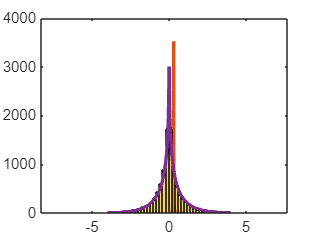

N = 10000;
standard_norm_vars1 = randn(1,N);
% histogram(standard_norm_vars1)
standard_norm_vars2 = randn(1,N);
% histogram(standard_norm_vars2)

norm_var_products = standard_norm_vars1.*standard_norm_vars2;


h = histogram(norm_var_products);
hold on
plot(-4:.01:4,N*h.BinWidth*besselk(0,abs(-4:.01:4))/pi,'LineWidth',2)
hold off

% Normalization Check
% integral(@(x) besselk(0,abs(x))/pi,-10,10)



A Modified Bessel Function with A Given Center (mean) and Spread (standard deviation)

center1 = 1/2;
center2 = 6/10;
spread1 = 1/20;
spread2 = 1/15;

bessel_center = center1*center2;
bessel_var = (spread1^2)*(spread2^2) + (center1^2)*(spread2^2) + (center2^2)*(spread1^2)

bessel_var = 0.0020

a = 1/sqrt(bessel_var);

my_function = @(z) a*besselk(0,a*abs(z-bessel_center))/pi;

% Normalization Check
integral(my_function,0,1);

actual_var = integral(@(z) (z-bessel_center).^2.*my_function(z),-10,10)

actual_var = 0.0020

A Theory About DSGs

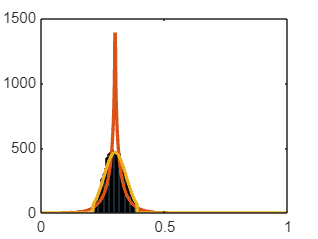

DSG_vars1 = double_stunted_gaussian_inverse_gamma(rand(1,N),center1,spread1);
% % histogram(DSG_vars1)
DSG_vars2 = double_stunted_gaussian_inverse_gamma(rand(1,N),center2,spread2);
% % histogram(DSG_vars2)

DSG_products = DSG_vars1.*DSG_vars2;
h = histogram(DSG_products);
hold on
plot(0:.001:1,N*h.BinWidth*my_function(0:.001:1),'LineWidth',2)
plot(0:.001:1,N*h.BinWidth*double_stunted_gaussian(0:.001:1,bessel_center,sqrt(bessel_var)),'LineWidth',2)
hold off


DSG_var = var(DSG_products)

DSG_var = 0.0016

All Together Now

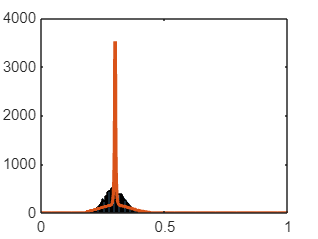

% Part 1: Modified Bessel Function with Mean = 0 and Standard
% Deviation spread1*spread2

function1 = @(z) besselk(0,abs(z)/spread1/spread2)/spread1/spread2/pi;

% Standard Deviation Check
% spread1*spread2
% sqrt(integral(@(z) (z).^2.*function1(z),-10,10))


% Part 2: Normal Distribution with Mean = 0 and Standard
% Deviation = spread1*center2 + spread2*center1

function2 = @(z) normpdf(z,0,spread1*center2+spread2*center1);

% Standard Deviation Check
% spread1*center2+spread2*center1
% sqrt(integral(@(z) (z).^2.*function2(z),-10,10))


my_function = @(z) ( z >= (center1-2*spread1)*(center2-2*spread2) & z <= (center1+2*spread1)*(center2+2*spread2) ) ...
    .* (function1(z-center1*center2)+function2(z-center1*center2));

my_function = @(z) 1/integral(@(x) my_function(x),-10,10)*my_function(z);

h = histogram(DSG_products);
hold on
plot(0:.001:1,N*h.BinWidth*my_function(0:.001:1),'LineWidth',2)


integral(@(z) my_function(z),0,1)

ans = 1.0000


% Standard Deviation Check
sqrt((spread1^2)*(spread2^2) + (center1^2)*(spread2^2) + (center2^2)*(spread1^2))

ans = 0.0450

sqrt(integral(@(z) (z-center1*center2).^2.*my_function(z),0,1))

ans = 0.0388